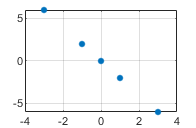

clear;

points = [0 0; -1 2; -3 6; 1 -2; 3 -6];

plot(points(:,1),points(:,2),'.', 'MarkerSize', 15);
grid on;


load USPS.mat
disp("Original first and second images:")

Original first and second images:


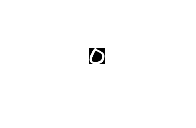

A1 = reshape(A(1, :), 16, 16);
imshow(A1')

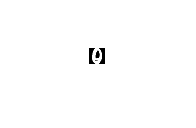

A2 = reshape(A(2, :), 16, 16);
imshow(A2')



AA = A;
for i=1:256
    AA(:, i) = A(:, i) - mean(A(:, i));
end




[u,s,v] = svd(AA);


pc10 = v(:, 1:10);
data10 = A * (pc10 * pc10');

disp("10 principal components images 1 and 2:")

10 principal components images 1 and 2:


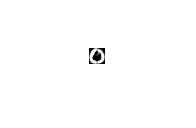

t1 = reshape(data10(1, :), 16, 16);
imshow(t1')

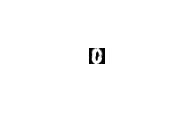

t2 = reshape(data10(2, :), 16, 16);
imshow(t2')


error = norm(A - data10);
disp("The reconstruction error for 10 principal components is:")

The reconstruction error for 10 principal components is:


disp(error)

  222.8360





pc50 = v(:, 1:50);
data50 = A * (pc50 * pc50');

disp("50 principal components images 1 and 2:")

50 principal components images 1 and 2:


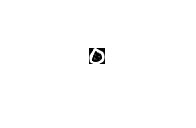

t1 = reshape(data50(1, :), 16, 16);
imshow(t1')

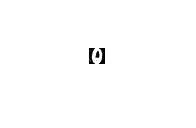

t2 = reshape(data50(2, :), 16, 16);
imshow(t2')


error = norm(A - data50);
disp("The reconstruction error for 50 principal components is:")

The reconstruction error for 50 principal components is:


disp(error)

   42.3531





pc100 = v(:, 1:100);
data100 = A * (pc100 * pc100');

disp("10 principal components images 1 and 2:")

10 principal components images 1 and 2:


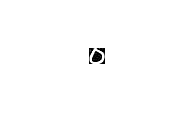

t1 = reshape(data100(1, :), 16, 16);
imshow(t1')

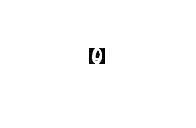

t2 = reshape(data100(2, :), 16, 16);
imshow(t2')


error = norm(A - data100);
disp("The reconstruction error for 100 principal components is:")

The reconstruction error for 100 principal components is:


disp(error)

   25.1730




pc200 = v(:, 1:200);
data200 = A * (pc200 * pc200');

disp("200 principal components images 1 and 2:")

200 principal components images 1 and 2:


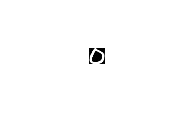

t1 = reshape(data200(1, :), 16, 16);
imshow(t1')

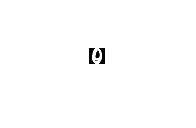

t2 = reshape(data200(2, :), 16, 16);
imshow(t2')



error = norm(A - data200);
disp("The reconstruction error for 200 principal components is:")

The reconstruction error for 200 principal components is:


disp(error)

    8.1191






%A2 = reshape(exmp(2, :), 16, 16);
%imshow(A2')